clear, clc
load('mitdb_dataset.mat')
ecg_mit = ecg;
Fs_mit = Fs;
%rr_mit = rr;
%rr_tm_mit = rr_tm; 
tm_mit = tm;
rrInterval = cell(23,1);

qrs_amp_raw = cell(23,1);
rr_tm_mit = cell(23,1);
delay = cell(23,1);

for i = 1:23 % DEPENDENCY ON TOOLBOX CONTAINING PAN_TOMPKIN2
    [qrs_amp_raw{i,1},rr_tm_mit{i,1},delay{i,1}] = pan_tompkin2(ecg{i,1},Fs_mit(i));
    rrInterval{i,1} = zeros(1,length(rr_tm_mit{i,1}));
    for z = 1:length(rrInterval{i,1})-1
        rrInterval{i,1}(z) = rr_tm_mit{i,1}(z+1) - rr_tm_mit{i,1}(z);
    end
end


%load('nstdb_dataset.mat')
%{
for fi = 1:23 
    data = ecg_mit{fi,1};
    n = length(data); 
    this_rr = rr_mit{fi,1};
    this_tm = rr_tm_mit{fi,1};
    %Split into segments by peaks
    samp_per_seg = (min(this_rr));
    segs = length(this_rr); 
    data_ar = [];
end
%}

recNum = 4;
DMatrix = ecg_mit{recNum,1}'; %Tested originally on "4" - need to loop through all patients
theseRRintervals = rrInterval{recNum,1};
medianSegLength = median(theseRRintervals);
mu_moving = movmean(DMatrix,medianSegLength);
data = DMatrix - mu_moving;
n = length(data);
rPeakStamps = rr_tm_mit{recNum,1};
numSegments = length(rPeakStamps);
segmentLength = 750;
%segment = nan(length(segmentLength));
segments = nan(numSegments,segmentLength);
startstopIndices = zeros(2,length(segments));
%start_index = 1;
%end_index = floor((rPeakStamps(2) - rPeakStamps(1))/2);
ecgStart = 1;
%ecgEnd = floor((rPeakStamps(2)-rPeakStamps(1))/2);
ecgEnd = rPeakStamps(1) + floor((rPeakStamps(2) - rPeakStamps(1))/2);
ecgLength = ecgEnd - ecgStart + 1;
delta = segmentLength - ecgLength;
segment = data(ecgStart:ecgEnd);
segStart = floor(delta/2);
segEnd = segmentLength - ceil(delta/2) - 1;
%segment(floor(delta/2)+1:segmentLength-ceil(delta/2)) = data(ecgStart:ecgEnd);
startstopIndices(:,1) = [segStart;segEnd];
segments(1,segStart:segEnd) = segment;



for i = 2:numSegments-1
    segment = [];
    %end_index = rPeakStamps(i) + ceil(segmentLength/2) - 1;
    ecgStart = ecgEnd+1;
    %ecgEnd = rPeakStamps(i) + floor((rPeakStamps(i+1)-rPeakStamps(i))/2) ;
    ecgEnd = rPeakStamps(i) + ceil((rPeakStamps(i+1) - rPeakStamps(i))/2);
    ecgLength = ecgEnd - ecgStart + 1;
    delta = segmentLength - ecgLength;
    segment = data(ecgStart:ecgEnd);
    segStart = floor(delta/2);
    segEnd = segmentLength - ceil(delta/2) - 1;
    startstopIndices(:,i) = [segStart;segEnd];
    segments(i, segStart:segEnd) = segment;
end

i = i+1;
ecgStart = ecgEnd+1;
ecgEnd = n;
ecgLength = ecgEnd - ecgStart + 1;
delta = segmentLength - ecgLength;
segment = data(ecgStart:ecgEnd);
segStart = floor(delta/2);
segEnd = segmentLength - ceil(delta/2) - 1;
startstopIndices(:,end) = [segStart;segEnd];
segments(end,segStart : segEnd) = segment;





row_means = mean(segments,2,'omitnan');
X_centered = segments - row_means;
segments2 = fillmissing(X_centered,'constant',0);
[centeredSegments, refTimes] = ecgsCentered(segments2,startstopIndices);




[coeff,score,latent,tsquared,explained,mu] = pca(centeredSegments);

P=1;
pcaDenoised = score(:,1:P) * coeff(:,1:P)' + row_means;
%reconstructed_signal = reconstructed_signal';




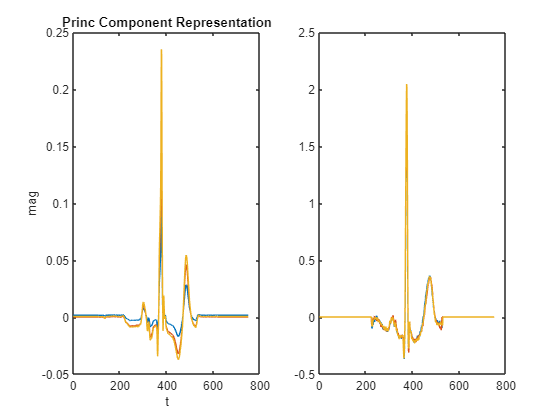

figure()
subplot(1,2,1)
plot(1:segmentLength,pcaDenoised(10:12,:))
xlabel('t')
ylabel('mag')
title('Princ Component Representation')
subplot(1,2,2)
plot(1:segmentLength,centeredSegments(10:12,:))